% Define the transfer function variable
s = tf('s');

% Given parameters
K = 0.92;
T = 0.414;
tau = 0.09;

% Calculate the required damping ratio and natural frequency
Mp = 0.025; % 2.5% overshoot
zeta = sqrt((log(Mp))^2 / (pi^2 + (log(Mp))^2));
settling_time = 0.7; % 0.7 seconds
omega_n = 4 / (zeta * settling_time);

% Trial and error for Kp, starting with an initial guess
Kp = 1;

% Plant without delay
G_no_delay = K / (T * s + 1)

G_no_delay =
 
     0.92
  -----------
  0.414 s + 1
 
Continuous-time transfer function.
Model Properties



% Plant with delay
G = G_no_delay * exp(-tau * s)

G =
 
                    0.92
  exp(-0.09*s) * -----------
                 0.414 s + 1
 
Continuous-time transfer function.
Model Properties



% P Controller
C = Kp;

% Smith Predictor Closed-loop Transfer Function
T_s = (C * G) / (1 + (C * G_no_delay))

T_s =
 
                       0.3809 s + 0.92
  exp(-0.09*s) * ---------------------------
                 0.1714 s^2 + 1.209 s + 1.92
 
Continuous-time transfer function.
Model Properties





% Analyze the step response and adjust Kp to achieve the desired specs
info = stepinfo(T_s)

info = struct with fields:
         RiseTime: 0.4737
    TransientTime: 0.9335
     SettlingTime: 0.9335
      SettlingMin: 0.4333
      SettlingMax: 0.4792
        Overshoot: 0
       Undershoot: 0
             Peak: 0.4792
         PeakTime: 3.1676



% Adjust Kp until the criteria are met
while info.Overshoot > 2.5 || info.SettlingTime > 0.7
    Kp = Kp * 1.1; % Increase Kp by 10%
    C = Kp;
    T_s = (C * G) / (1 + (C * G_no_delay))
    info = stepinfo(T_s);
end

T_s =
 
                       0.419 s + 1.012
  exp(-0.09*s) * ----------------------------
                 0.1714 s^2 + 1.247 s + 2.012
 
Continuous-time transfer function.
Model Properties

T_s =
 
                       0.4609 s + 1.113
  exp(-0.09*s) * ----------------------------
                 0.1714 s^2 + 1.289 s + 2.113
 
Continuous-time transfer function.



% Display the final value of Kp
fprintf('Final value of Kp: %.4f\n', Kp);

Final value of Kp: 1.9487


info = stepinfo(T_s)

info = struct with fields:
         RiseTime: 0.3257
    TransientTime: 0.6699
     SettlingTime: 0.6699
      SettlingMin: 0.5801
      SettlingMax: 0.6417
        Overshoot: 0
       Undershoot: 0
             Peak: 0.6417
         PeakTime: 1.2902


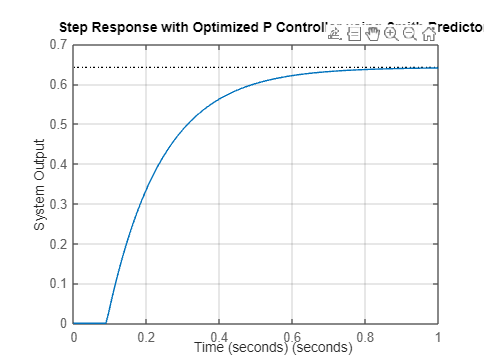

% Plot the final step response
figure;
step(T_s);
title('Step Response with Optimized P Controller using Smith Predictor');
xlabel('Time (seconds)');
ylabel('System Output');
grid on;